**Analyse synergies sujet par sujet**

**Base**

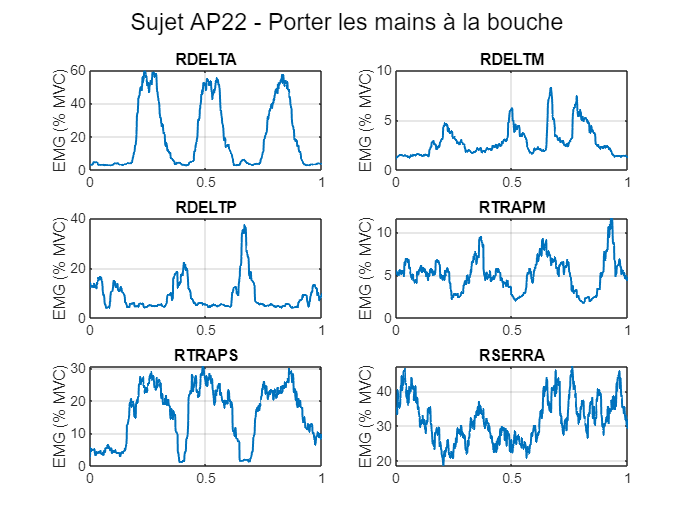

clc, clear all; 

% Ajout de la bibliothèque btk
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition sujet (15 au total)
subjects = {'AP22'}; % Marche uniquement pour un sujet
%'MF01', 'TF02', 'YL03', 'AP06', 'TD07', 'IS08', 'LC09', 'PK11', 'JM13'
%'LD15', 'JV18', 'MG20', 'AP22', 'SC23', 'TM24'

nb_subjects = length(subjects);

% Définition des muscles (choisir droite ou gauche)
muscles = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RSERRA'};
% muscles = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPM', 'LTRAPS', 'LSERRA'};
nb_muscles = length(muscles);

% Définition des labels pour les tâches
functional_labels = {...
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'};
analytic_labels = { 
    'Flexion (élévation sagittale)', ...
    'Abduction (élévation coronale)', ...
    'Rotation externe (abduction 0°)', ...
    'Rotation interne (abduction 0°)'};

nb_functional = length(functional_labels);
nb_analytic = length(analytic_labels);

% Paramètres EMG
fs = 2000;
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass');
rms_window = round(0.250 * fs);
num_points = 1000;
time_normalized = linspace(0, 1, num_points);


% Association Muscle -> Tâche Analytique définie manuellement
assigned_analytics = [1, 2, 2, 2, 2, 2]; %4

% Initialisation des MVC des tâches analytiques
mvc = zeros(nb_muscles, 1);
all_functional_data = cell(nb_subjects, nb_functional, nb_muscles);

% Calcul du MVC basé sur la tâche analytique assignée
for subj_idx = 1:nb_subjects
    for m = 1:nb_muscles
        analytic_idx = assigned_analytics(m);
        
        fileName_analytic = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
            '%s-%s-20240101-PROTOCOL01-ANALYTIC%d-.c3d'], ...
            subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, analytic_idx);
        
        c3dH_analytic = btkReadAcquisition(fileName_analytic);
        analogs_analytic = btkGetAnalogs(c3dH_analytic);
        
        muscle_name = muscles{m};
        if isfield(analogs_analytic, muscle_name)
            signal = analogs_analytic.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(abs(signal_filtered));
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            sorted_rms = sort(emg_rms, 'descend');
            mvc(m) = mean(sorted_rms(1:5));
        end
    end
end

% Sélection d'une tâche fonctionnelle unique
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Traitement des données
for subj_idx = 1:nb_subjects
    fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_functional);
    
    c3dH_functional = btkReadAcquisition(fileName_functional);
    analogs_functional = btkGetAnalogs(c3dH_functional);
    
    figure;
    sgtitle(sprintf('Sujet %s - %s', subjects{subj_idx}, functional_labels{selected_functional}));
    
    for m = 1:nb_muscles
        subplot(ceil(nb_muscles/2), 2, m);
        muscle_name = muscles{m};
        if isfield(analogs_functional, muscle_name)
            signal = analogs_functional.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(abs(signal_filtered));
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            
            % Normalisation du temps
            time_original = linspace(0, 1, length(emg_rms));
            emg_interp = interp1(time_original, emg_rms, time_normalized, 'spline');
            
            % Normalisation par le MVC associé à la tâche prédéfinie
            emg_normalized = (emg_interp / mvc(m)) * 100;

            all_functional_data{subj_idx, selected_functional, m} = emg_normalized;
            plot(time_normalized, emg_normalized, 'LineWidth', 1.2);
            title(muscle_name);
            ylabel('EMG (% MVC)');
            grid on;
        else
            title(sprintf('%s (Données absentes)', muscle_name));
        end
    end
end


subject_idx = 1;
functional_idx = selected_functional;

data_matrix_TF02_R = zeros(nb_muscles, num_points);
for m = 1:nb_muscles
    data_matrix_TF02_R(m, :) = all_functional_data{subject_idx, functional_idx, m};
end

**3 cycles (repère DELTA)**

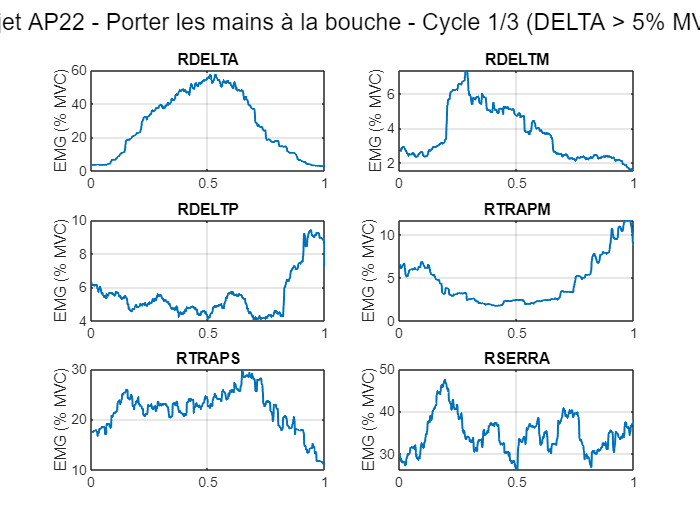

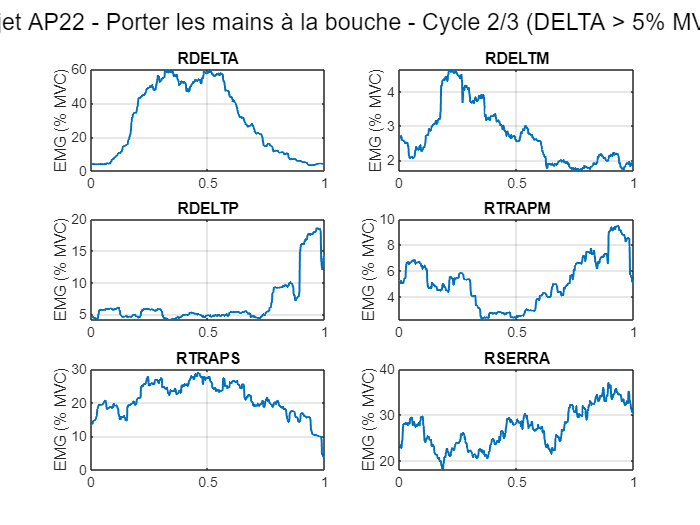

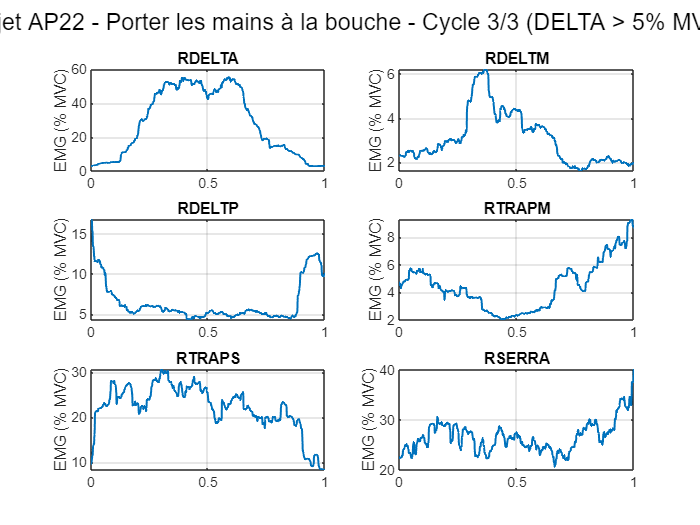

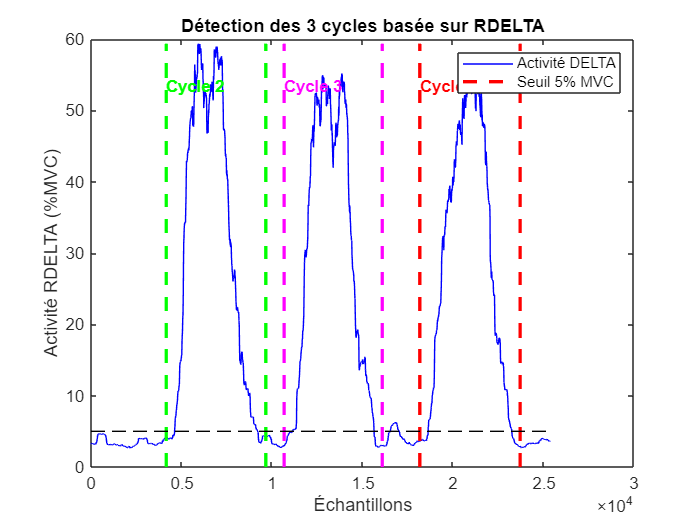

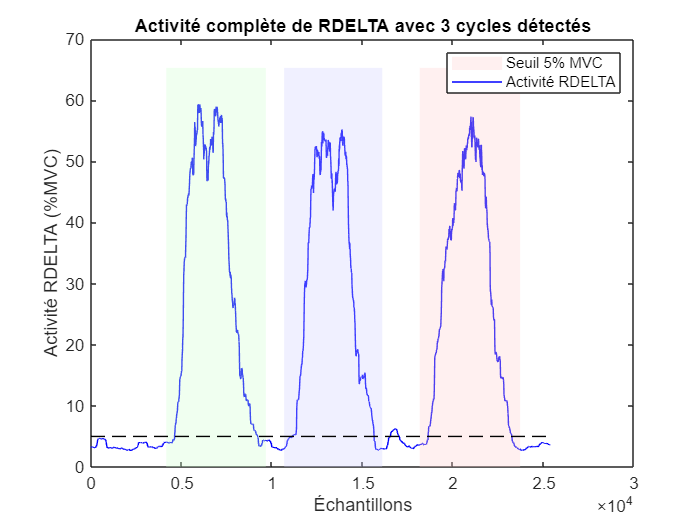

clc, clear all; 

% Ajout de la bibliothèque btk
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition sujet (15 au total)
subjects = {'AP22'}; % Marche uniquement pour un sujet
%'MF01', 'TF02', 'YL03', 'AP06', 'TD07', 'IS08', 'LC09', 'PK11', 'JM13'
%'LD15', 'JV18', 'MG20', 'AP22', 'SC23', 'TM24'

nb_subjects = length(subjects);

% Définition des muscles (choisir droite ou gauche)
muscles = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RSERRA'};
% muscles = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPM', 'LTRAPS', 'LSERRA'};
nb_muscles = length(muscles);

% Index du muscle DELTA (première position dans la liste)
delta_idx = 1; % RDELTA est à la position 1 dans la liste des muscles

% Définition des labels pour les tâches
functional_labels = {...
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'};
analytic_labels = { 
    'Flexion (élévation sagittale)', ...
    'Abduction (élévation coronale)', ...
    'Rotation externe (abduction 0°)', ...
    'Rotation interne (abduction 0°)'};

nb_functional = length(functional_labels);
nb_analytic = length(analytic_labels);

% Paramètres EMG
fs = 2000;
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass');
rms_window = round(0.250 * fs);
num_points = 1000;
time_normalized = linspace(0, 1, num_points);

% Seuil d'activité DELTA (5% du MVC)
delta_threshold_percent = 5; 
min_duration = 0.1;  % Durée minimale d'un mouvement (en secondes)
num_cycles = 3;      % Nombre de cycles à traiter

% Association Muscle -> Tâche Analytique définie manuellement
assigned_analytics = [1, 2, 2, 2, 2, 2]; %4

% Initialisation des MVC des tâches analytiques
mvc = zeros(nb_muscles, 1);
all_functional_data = cell(nb_subjects, nb_functional, nb_muscles, num_cycles);

% Calcul du MVC basé sur la tâche analytique assignée
for subj_idx = 1:nb_subjects
    for m = 1:nb_muscles
        analytic_idx = assigned_analytics(m);
        
        fileName_analytic = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
            '%s-%s-20240101-PROTOCOL01-ANALYTIC%d-.c3d'], ...
            subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, analytic_idx);
        
        c3dH_analytic = btkReadAcquisition(fileName_analytic);
        analogs_analytic = btkGetAnalogs(c3dH_analytic);
        
        muscle_name = muscles{m};
        if isfield(analogs_analytic, muscle_name)
            signal = analogs_analytic.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(abs(signal_filtered));
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            sorted_rms = sort(emg_rms, 'descend');
            mvc(m) = mean(sorted_rms(1:5));
        end
    end
end

% Sélection d'une tâche fonctionnelle unique
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Traitement des données
for subj_idx = 1:nb_subjects
    fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_functional);
    
    c3dH_functional = btkReadAcquisition(fileName_functional);
    analogs_functional = btkGetAnalogs(c3dH_functional);
    
    % Extraction et traitement du signal DELTA pour la détection du mouvement
    delta_muscle = muscles{delta_idx};
    if isfield(analogs_functional, delta_muscle)
        signal_delta = analogs_functional.(delta_muscle);
        signal_filtered_delta = filtfilt(b, a, signal_delta);
        signal_abs_delta = abs(abs(signal_filtered_delta));
        emg_rms_delta = sqrt(movmean(signal_abs_delta.^2, rms_window));
        
        % Normalisation par le MVC du DELTA
        emg_normalized_delta = (emg_rms_delta / mvc(delta_idx)) * 100;
        
        % Seuil basé sur le pourcentage spécifié du MVC de DELTA
        delta_threshold = delta_threshold_percent;
        
        % Détection du début et de la fin du mouvement basée sur DELTA
        movement_mask = emg_normalized_delta > delta_threshold;
        
        % Appliquer une durée minimale (filtrage des activations courtes)
        min_samples = round(min_duration * fs);
        movement_mask = bwareaopen(movement_mask, min_samples);
        
        % Trouver les indices de début et fin
        movement_regions = regionprops(movement_mask, 'PixelIdxList');
        
        cycle_info = [];
        
        if ~isempty(movement_regions)
            % Fusionner les régions proches
            connected_regions = [];
            max_gap = round(0.3 * fs); % 300 ms maximum entre les régions à fusionner
            
            % Trier les régions par leurs indices de début
            starts = cellfun(@min, {movement_regions.PixelIdxList});
            ends = cellfun(@max, {movement_regions.PixelIdxList});
            [~, sort_idx] = sort(starts);
            movement_regions = movement_regions(sort_idx);
            starts = starts(sort_idx);
            ends = ends(sort_idx);
            
            % Fusionner les régions avec un écart faible
            current_start = starts(1);
            current_end = ends(1);
            
            for i = 2:length(movement_regions)
                if starts(i) - current_end <= max_gap
                    % Fusionner avec la région actuelle
                    current_end = ends(i);
                else
                    % Sauvegarder la région actuelle et commencer une nouvelle
                    connected_regions = [connected_regions; current_start, current_end];
                    current_start = starts(i);
                    current_end = ends(i);
                end
            end
            % Ajouter la dernière région
            connected_regions = [connected_regions; current_start, current_end];
            
            % Trier les régions fusionnées par durée
            region_durations = connected_regions(:,2) - connected_regions(:,1);
            [sorted_durations, sort_idx] = sort(region_durations, 'descend');
            connected_regions = connected_regions(sort_idx, :);
            
            % Sélectionner les trois plus grandes régions (ou moins si pas assez disponibles)
            num_available_cycles = min(num_cycles, size(connected_regions, 1));
            
            for cycle = 1:num_available_cycles
                movement_start = connected_regions(cycle, 1);
                movement_end = connected_regions(cycle, 2);
                
                % Ajouter une marge avant et après (10% de la durée du mouvement)
                margin = round((movement_end - movement_start) * 0.1);
                movement_start = max(1, movement_start - margin);
                movement_end = min(length(emg_normalized_delta), movement_end + margin);
                
                cycle_info(cycle, :) = [movement_start, movement_end];
            end
        else
            % Si aucun mouvement détecté, utiliser l'ensemble des données comme un seul cycle
            cycle_info(1, :) = [1, length(emg_normalized_delta)];
            num_available_cycles = 1;
        end
    else
        % Si le muscle DELTA n'est pas disponible, utiliser l'ensemble des données
        cycle_info(1, :) = [1, length(analogs_functional.(muscles{1}))];
        num_available_cycles = 1;
        warning('Muscle DELTA non disponible. Utilisation de toutes les données.');
    end
    
    % Afficher les résultats pour chaque cycle
    for cycle = 1:num_available_cycles
        movement_start = cycle_info(cycle, 1);
        movement_end = cycle_info(cycle, 2);
        
        figure;
        sgtitle(sprintf('Sujet %s - %s - Cycle %d/%d (DELTA > %d%% MVC)', ...
            subjects{subj_idx}, functional_labels{selected_functional}, ...
            cycle, num_available_cycles, delta_threshold_percent));
        
        for m = 1:nb_muscles
            subplot(ceil(nb_muscles/2), 2, m);
            muscle_name = muscles{m};
            if isfield(analogs_functional, muscle_name)
                signal = analogs_functional.(muscle_name);
                signal_filtered = filtfilt(b, a, signal);
                signal_abs = abs(abs(signal_filtered));
                emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
                
                % Extraire uniquement la partie correspondant au mouvement
                emg_movement = emg_rms(movement_start:movement_end);
                
                % Normalisation du temps
                time_original = linspace(0, 1, length(emg_movement));
                emg_interp = interp1(time_original, emg_movement, time_normalized, 'spline');
                
                % Normalisation par le MVC associé à la tâche prédéfinie
                emg_normalized = (emg_interp / mvc(m)) * 100;
                
                all_functional_data{subj_idx, selected_functional, m, cycle} = emg_normalized;
                plot(time_normalized, emg_normalized, 'LineWidth', 1.2);
                title(muscle_name);
                ylabel('EMG (% MVC)');
                grid on;
            else
                title(sprintf('%s (Données absentes)', muscle_name));
            end
        end
    end
    
    % Figure supplémentaire pour montrer la détection des trois cycles
    if exist('emg_normalized_delta', 'var')
        figure;
        plot(emg_normalized_delta, 'b');
        hold on;
        colors = {'r', 'g', 'm'};
        
        for cycle = 1:num_available_cycles
            movement_start = cycle_info(cycle, 1);
            movement_end = cycle_info(cycle, 2);
            color_idx = mod(cycle-1, length(colors)) + 1;
            
            % Tracer des lignes verticales pour chaque cycle
            plot([movement_start movement_start], [0 max(emg_normalized_delta)], ...
                [colors{color_idx} '--'], 'LineWidth', 2);
            plot([movement_end movement_end], [0 max(emg_normalized_delta)], ...
                [colors{color_idx} '--'], 'LineWidth', 2);
            
            % Ajouter une étiquette
            text(movement_start, max(emg_normalized_delta)*0.9, ...
                sprintf('Cycle %d', cycle), 'Color', colors{color_idx}, 'FontWeight', 'bold');
        end
        
        plot([1 length(emg_normalized_delta)], [delta_threshold delta_threshold], 'k--');
        title(sprintf('Détection des %d cycles basée sur %s', num_available_cycles, delta_muscle));
        xlabel('Échantillons');
        ylabel(sprintf('Activité %s (%%MVC)', delta_muscle));
        legend('Activité DELTA', 'Seuil 5% MVC');
        
        % Créer une version de la figure montrant toute l'activité avec des zones colorées
        figure;
        plot(emg_normalized_delta, 'b');
        hold on;
        
        % Mettre en évidence les zones actives avec différentes couleurs
        y_max = max(emg_normalized_delta) * 1.1;
        color_alphas = {[1 0.8 0.8], [0.8 1 0.8], [0.8 0.8 1]};
        
        for cycle = 1:num_available_cycles
            movement_start = cycle_info(cycle, 1);
            movement_end = cycle_info(cycle, 2);
            color_idx = mod(cycle-1, length(color_alphas)) + 1;
            
            % Coloration des zones actives
            movement_mask_viz = zeros(size(emg_normalized_delta));
            movement_mask_viz(movement_start:movement_end) = 1;
            area_x = 1:length(emg_normalized_delta);
            area_y = y_max * movement_mask_viz;
            area(area_x, area_y, 'FaceColor', color_alphas{color_idx}, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
        end
        
        plot([1 length(emg_normalized_delta)], [delta_threshold delta_threshold], 'k--');
        title(sprintf('Activité complète de %s avec %d cycles détectés', delta_muscle, num_available_cycles));
        xlabel('Échantillons');
        ylabel(sprintf('Activité %s (%%MVC)', delta_muscle));
        legend(['Activité ' delta_muscle], 'Seuil 5% MVC');
    end
end

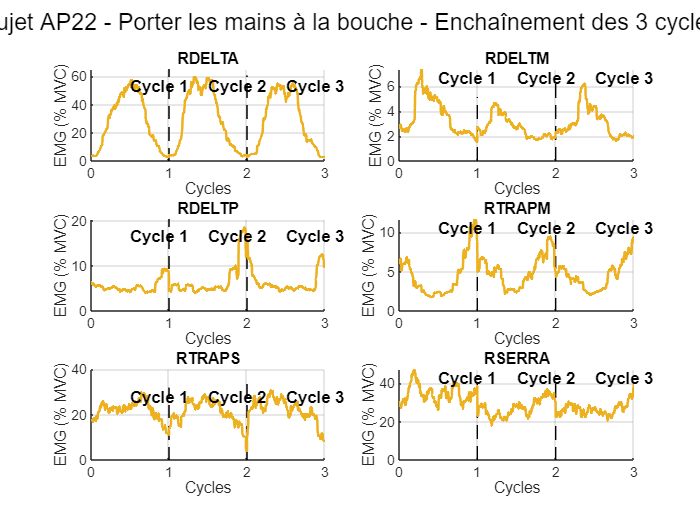


% Afficher l'enchaînement des cycles au lieu de la moyenne
% Récupération des données pour tous les cycles
subject_idx = 1;
functional_idx = selected_functional;

% Créer une figure pour l'enchaînement des cycles pour tous les muscles
figure;
sgtitle(sprintf('Sujet %s - %s - Enchaînement des %d cycles', subjects{1}, functional_labels{selected_functional}, num_available_cycles));

for m = 1:nb_muscles
    subplot(ceil(nb_muscles/2), 2, m);
    hold on;
    
    % Concaténer les données des cycles valides
    all_cycles_data = [];
    
    for cycle = 1:num_cycles
        cycle_data = all_functional_data{subject_idx, functional_idx, m, cycle};
        if ~isempty(cycle_data)
            % Ajouter une ligne verticale pour séparer les cycles (sauf avant le premier)
            if ~isempty(all_cycles_data)
                % Ajouter une ligne verticale à la fin du dernier cycle
                line([length(all_cycles_data)/num_points length(all_cycles_data)/num_points], [0 max(cycle_data)*1.1], 'Color', 'k', 'LineStyle', '--');
            end
            
            % Concaténer les données
            all_cycles_data = [all_cycles_data, cycle_data];
        end
    end
    
    % Créer un vecteur de temps pour l'enchaînement des cycles
    time_concatenated = linspace(0, length(all_cycles_data)/num_points, length(all_cycles_data));
    
    % Tracer l'enchaînement des cycles
    plot(time_concatenated, all_cycles_data, 'LineWidth', 1.5);
    
    % Ajouter des annotations pour les cycles
    for cycle = 1:num_available_cycles
        cycle_start = (cycle-1);
        text(cycle_start + 0.5, max(all_cycles_data)*0.9, sprintf('Cycle %d', cycle), 'FontWeight', 'bold');
    end
    
    title(muscles{m});
    ylabel('EMG (% MVC)');
    xlabel('Cycles');
    grid on;
end



% Création d'une grande matrice pour sauvegarder les données
% Format: 6 muscles (lignes) x temps concaténé pour les 3 cycles (colonnes)
all_data_matrix = zeros(nb_muscles, num_points * num_available_cycles);

% Remplissage de la matrice
for m = 1:nb_muscles
    col_start = 1;
    
    for cycle = 1:num_available_cycles
        cycle_data = all_functional_data{subject_idx, functional_idx, m, cycle};
        
        if ~isempty(cycle_data)
            % Calculer l'indice de fin pour ce cycle
            col_end = col_start + length(cycle_data) - 1;
            
            % S'assurer que nous ne dépassons pas les limites de la matrice
            if col_end <= size(all_data_matrix, 2)
                all_data_matrix(m, col_start:col_end) = cycle_data;
            else
                % Ajuster la taille si nécessaire
                all_data_matrix(m, col_start:size(all_data_matrix, 2)) = cycle_data(1:(size(all_data_matrix, 2)-col_start+1));
            end
            
            % Mettre à jour l'indice de début pour le prochain cycle
            col_start = col_end + 1;
        end
    end
end

% Affichage de la taille de la matrice pour vérification
fprintf('Matrice de données créée avec %d muscles et %d points temporels\n', ...
    size(all_data_matrix, 1), size(all_data_matrix, 2));

Matrice de données créée avec 6 muscles et 3000 points temporels



% Sauvegarde de la matrice dans un fichier .mat
save_filename = sprintf('%s_functional%d_data.mat', subjects{1}, functional_idx);
save(save_filename, 'all_data_matrix', 'muscles', 'functional_labels', 'selected_functional', 'subjects');

fprintf('Données sauvegardées dans le fichier: %s\n', save_filename);

Données sauvegardées dans le fichier: AP22_functional1_data.mat



% Optionnel: Création d'une table pour une meilleure visualisation des données
muscle_names = cell(nb_muscles, 1);
for m = 1:nb_muscles
    muscle_names{m} = muscles{m};
end

all_data_table = array2table(all_data_matrix, 'RowNames', muscle_names);

**3 cycles (repère marqueur de la main)**

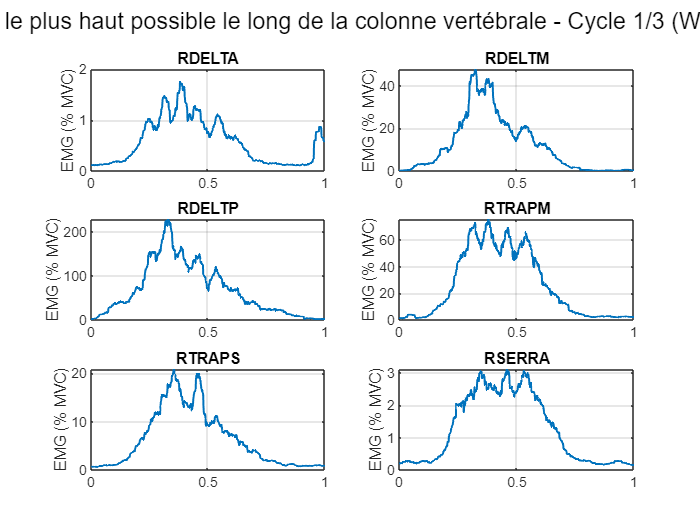

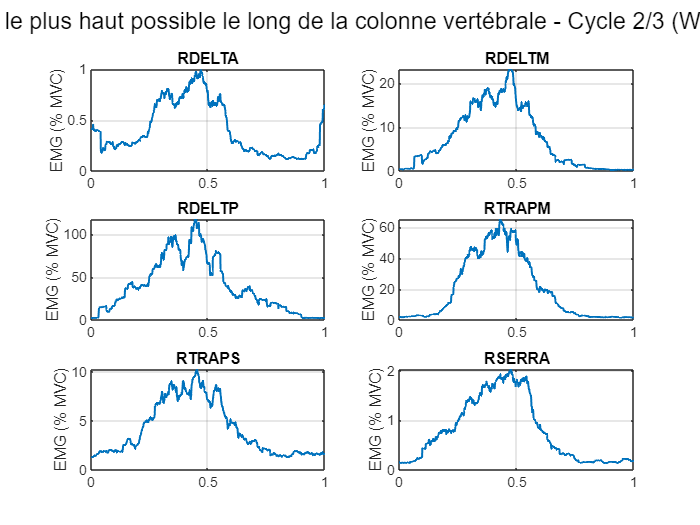

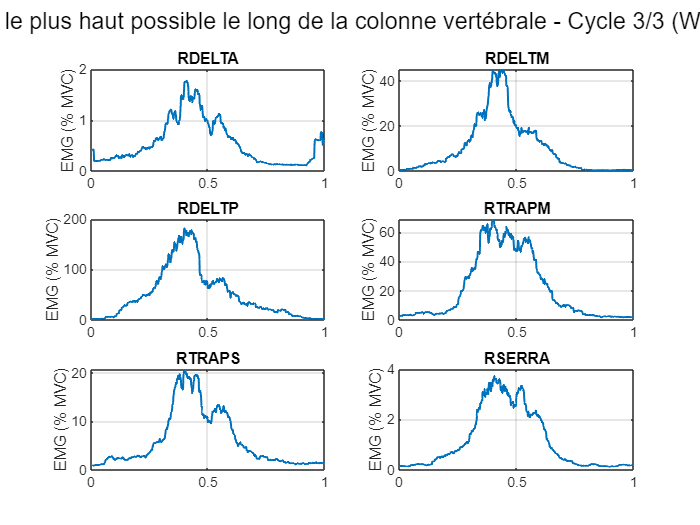

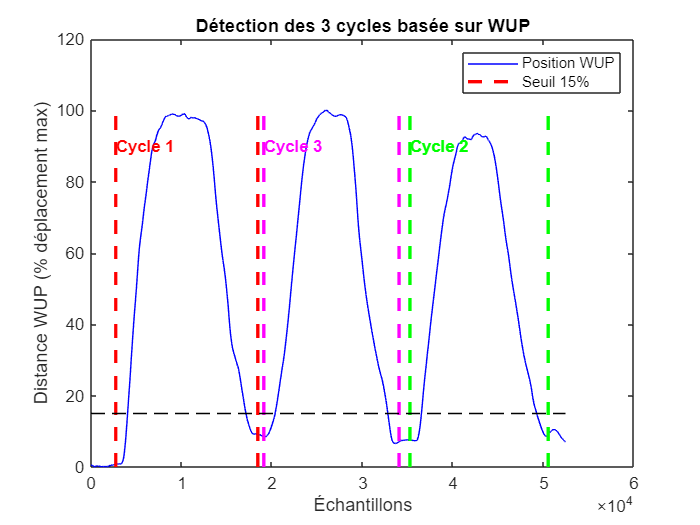

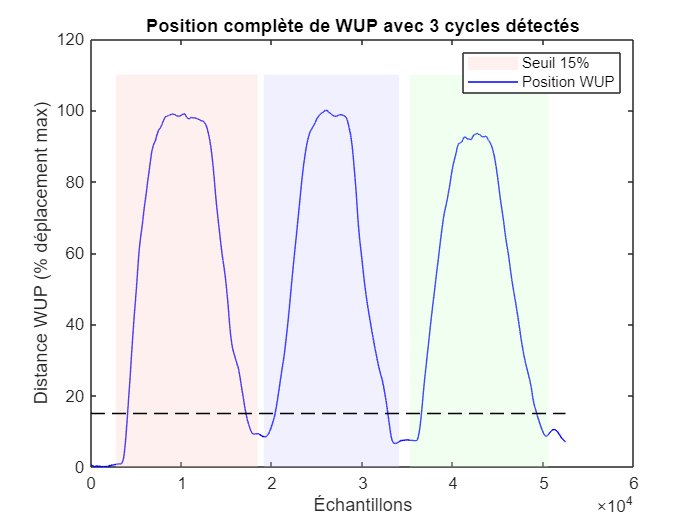

clc, clear all; 

% Ajout de la bibliothèque btk
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition sujet (15 au total)
subjects = {'YL03'}; % Marche uniquement pour un sujet
%'MF01', 'TF02', 'YL03', 'AP06', 'TD07', 'IS08', 'LC09', 'PK11', 'JM13'
%'LD15', 'JV18', 'MG20', 'AP22', 'SC23', 'TM24'

nb_subjects = length(subjects);

% Définition des muscles (choisir droite ou gauche)
muscles = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RSERRA'};
% muscles = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPM', 'LTRAPS', 'LSERRA'};
nb_muscles = length(muscles);

% Définition des labels pour les tâches
functional_labels = {...
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'};
analytic_labels = { 
    'Flexion (élévation sagittale)', ...
    'Abduction (élévation coronale)', ...
    'Rotation externe (abduction 0°)', ...
    'Rotation interne (abduction 0°)'};

nb_functional = length(functional_labels);
nb_analytic = length(analytic_labels);

% Paramètres EMG
fs = 2000;
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass');
rms_window = round(0.250 * fs);
num_points = 1000;
time_normalized = linspace(0, 1, num_points);

% Paramètres pour la détection basée sur le marqueur WUP
position_threshold_percent = 15;  % Seuil de déplacement significatif (% du déplacement max)
min_duration = 0.1;  % Durée minimale d'un mouvement (en secondes)
num_cycles = 3;      % Nombre de cycles à traiter

% Association Muscle -> Tâche Analytique définie manuellement
assigned_analytics = [1, 2, 2, 2, 2, 2]; %4

% Initialisation des MVC des tâches analytiques
mvc = zeros(nb_muscles, 1);
all_functional_data = cell(nb_subjects, nb_functional, nb_muscles, num_cycles);

% Calcul du MVC basé sur la tâche analytique assignée
for subj_idx = 1:nb_subjects
    for m = 1:nb_muscles
        analytic_idx = assigned_analytics(m);
        
        fileName_analytic = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
            '%s-%s-20240101-PROTOCOL01-ANALYTIC%d-.c3d'], ...
            subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, analytic_idx);
        
        c3dH_analytic = btkReadAcquisition(fileName_analytic);
        analogs_analytic = btkGetAnalogs(c3dH_analytic);
        
        muscle_name = muscles{m};
        if isfield(analogs_analytic, muscle_name)
            signal = analogs_analytic.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(abs(signal_filtered));
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            sorted_rms = sort(emg_rms, 'descend');
            mvc(m) = mean(sorted_rms(1:5));
        end
    end
end

% Sélection d'une tâche fonctionnelle unique
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Traitement des données
for subj_idx = 1:nb_subjects
    fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_functional);
    
    c3dH_functional = btkReadAcquisition(fileName_functional);
    analogs_functional = btkGetAnalogs(c3dH_functional);
    
    % Extraction des données du marqueur WUP
    points = btkGetPoints(c3dH_functional);
    markers = fieldnames(points);
    
    % Vérifier si le marqueur WUP existe
    if ismember('RWUP', markers)
        % Extraction des coordonnées 3D du marqueur WUP
        wup_pos = points.RWUP;
        
        % Calculer la position de référence (position de départ)
        % Utiliser les 100 premiers échantillons pour calculer la position moyenne de départ
        wup_baseline = mean(wup_pos(1:100, :));
        
        % Calculer la distance euclidienne entre la position actuelle et la position de référence
        wup_distance = sqrt(sum((wup_pos - repmat(wup_baseline, size(wup_pos, 1), 1)).^2, 2));
        
        % Normaliser la distance par la distance maximale
        wup_distance_max = max(wup_distance);
        wup_distance_normalized = (wup_distance / wup_distance_max) * 100;
        
        % Adapter la fréquence d'échantillonnage du marqueur (généralement 100 Hz) à celle de l'EMG (2000 Hz)
        markers_fs = btkGetPointFrequency(c3dH_functional);
        emg_fs = btkGetAnalogFrequency(c3dH_functional);
        ratio = emg_fs / markers_fs;
        
        % Interpoler les données du marqueur pour correspondre à la fréquence EMG
        t_marker = (0:length(wup_distance_normalized)-1) / markers_fs;
        t_emg = (0:ratio*length(wup_distance_normalized)-1) / emg_fs;
        wup_distance_resampled = interp1(t_marker, wup_distance_normalized, t_emg, 'spline');
        
        % Ajuster la longueur pour correspondre aux données EMG (si nécessaire)
        max_length = min([length(wup_distance_resampled), length(analogs_functional.(muscles{1}))]);
        wup_distance_resampled = wup_distance_resampled(1:max_length);
        
        % Définir le seuil de détection basé sur le pourcentage du déplacement maximal
        position_threshold = position_threshold_percent;
        
        % Détection du début et de la fin du mouvement basée sur la position de WUP
        movement_mask = wup_distance_resampled > position_threshold;
        
        % Appliquer une durée minimale (filtrage des activations courtes)
        min_samples = round(min_duration * fs);
        movement_mask = bwareaopen(movement_mask, min_samples);
        
        % Trouver les indices de début et fin
        movement_regions = regionprops(movement_mask, 'PixelIdxList');
        
        cycle_info = [];
        
        if ~isempty(movement_regions)
            % Fusionner les régions proches
            connected_regions = [];
            max_gap = round(0.3 * fs); % 300 ms maximum entre les régions à fusionner
            
            % Trier les régions par leurs indices de début
            starts = cellfun(@min, {movement_regions.PixelIdxList});
            ends = cellfun(@max, {movement_regions.PixelIdxList});
            [~, sort_idx] = sort(starts);
            movement_regions = movement_regions(sort_idx);
            starts = starts(sort_idx);
            ends = ends(sort_idx);
            
            % Fusionner les régions avec un écart faible
            current_start = starts(1);
            current_end = ends(1);
            
            for i = 2:length(movement_regions)
                if starts(i) - current_end <= max_gap
                    % Fusionner avec la région actuelle
                    current_end = ends(i);
                else
                    % Sauvegarder la région actuelle et commencer une nouvelle
                    connected_regions = [connected_regions; current_start, current_end];
                    current_start = starts(i);
                    current_end = ends(i);
                end
            end
            % Ajouter la dernière région
            connected_regions = [connected_regions; current_start, current_end];
            
            % Trier les régions fusionnées par durée
            region_durations = connected_regions(:,2) - connected_regions(:,1);
            [sorted_durations, sort_idx] = sort(region_durations, 'descend');
            connected_regions = connected_regions(sort_idx, :);
            
            % Sélectionner les trois plus grandes régions (ou moins si pas assez disponibles)
            num_available_cycles = min(num_cycles, size(connected_regions, 1));
            
            for cycle = 1:num_available_cycles
                movement_start = connected_regions(cycle, 1);
                movement_end = connected_regions(cycle, 2);
                
                % Ajouter une marge avant et après (10% de la durée du mouvement)
                margin = round((movement_end - movement_start) * 0.1);
                movement_start = max(1, movement_start - margin);
                movement_end = min(max_length, movement_end + margin);
                
                cycle_info(cycle, :) = [movement_start, movement_end];
            end
        else
            % Si aucun mouvement détecté, utiliser l'ensemble des données comme un seul cycle
            cycle_info(1, :) = [1, max_length];
            num_available_cycles = 1;
        end
    else
        % Si le marqueur WUP n'est pas disponible, utiliser l'ensemble des données
        cycle_info(1, :) = [1, length(analogs_functional.(muscles{1}))];
        num_available_cycles = 1;
        warning('Marqueur WUP non disponible. Utilisation de toutes les données.');
    end
    
    % Afficher les résultats pour chaque cycle
    for cycle = 1:num_available_cycles
        movement_start = cycle_info(cycle, 1);
        movement_end = cycle_info(cycle, 2);
        
        figure;
        sgtitle(sprintf('Sujet %s - %s - Cycle %d/%d (WUP > %d%% déplacement max)', ...
            subjects{subj_idx}, functional_labels{selected_functional}, ...
            cycle, num_available_cycles, position_threshold_percent));
        
        for m = 1:nb_muscles
            subplot(ceil(nb_muscles/2), 2, m);
            muscle_name = muscles{m};
            if isfield(analogs_functional, muscle_name)
                signal = analogs_functional.(muscle_name);
                signal_filtered = filtfilt(b, a, signal);
                signal_abs = abs(abs(signal_filtered));
                emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
                
                % Extraire uniquement la partie correspondant au mouvement
                emg_movement = emg_rms(movement_start:movement_end);
                
                % Normalisation du temps
                time_original = linspace(0, 1, length(emg_movement));
                emg_interp = interp1(time_original, emg_movement, time_normalized, 'spline');
                
                % Normalisation par le MVC associé à la tâche prédéfinie
                emg_normalized = (emg_interp / mvc(m)) * 100;
                
                all_functional_data{subj_idx, selected_functional, m, cycle} = emg_normalized;
                plot(time_normalized, emg_normalized, 'LineWidth', 1.2);
                title(muscle_name);
                ylabel('EMG (% MVC)');
                grid on;
            else
                title(sprintf('%s (Données absentes)', muscle_name));
            end
        end
    end
    
    % Figure supplémentaire pour montrer la détection des trois cycles
    if exist('wup_distance_resampled', 'var')
        figure;
        plot(wup_distance_resampled, 'b');
        hold on;
        colors = {'r', 'g', 'm'};
        
        for cycle = 1:num_available_cycles
            movement_start = cycle_info(cycle, 1);
            movement_end = cycle_info(cycle, 2);
            color_idx = mod(cycle-1, length(colors)) + 1;
            
            % Tracer des lignes verticales pour chaque cycle
            plot([movement_start movement_start], [0 max(wup_distance_resampled)], ...
                [colors{color_idx} '--'], 'LineWidth', 2);
            plot([movement_end movement_end], [0 max(wup_distance_resampled)], ...
                [colors{color_idx} '--'], 'LineWidth', 2);
            
            % Ajouter une étiquette
            text(movement_start, max(wup_distance_resampled)*0.9, ...
                sprintf('Cycle %d', cycle), 'Color', colors{color_idx}, 'FontWeight', 'bold');
        end
        
        plot([1 length(wup_distance_resampled)], [position_threshold position_threshold], 'k--');
        title(sprintf('Détection des %d cycles basée sur WUP', num_available_cycles));
        xlabel('Échantillons');
        ylabel('Distance WUP (% déplacement max)');
        legend('Position WUP', sprintf('Seuil %d%%', position_threshold_percent));
        
        % Créer une version de la figure montrant toute l'activité avec des zones colorées
        figure;
        plot(wup_distance_resampled, 'b');
        hold on;
        
        % Mettre en évidence les zones actives avec différentes couleurs
        y_max = max(wup_distance_resampled) * 1.1;
        color_alphas = {[1 0.8 0.8], [0.8 1 0.8], [0.8 0.8 1]};
        
        for cycle = 1:num_available_cycles
            movement_start = cycle_info(cycle, 1);
            movement_end = cycle_info(cycle, 2);
            color_idx = mod(cycle-1, length(color_alphas)) + 1;
            
            % Coloration des zones actives
            movement_mask_viz = zeros(size(wup_distance_resampled));
            movement_mask_viz(movement_start:movement_end) = 1;
            area_x = 1:length(wup_distance_resampled);
            area_y = y_max * movement_mask_viz;
            area(area_x, area_y, 'FaceColor', color_alphas{color_idx}, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
        end
        
        plot([1 length(wup_distance_resampled)], [position_threshold position_threshold], 'k--');
        title(sprintf('Position complète de WUP avec %d cycles détectés', num_available_cycles));
        xlabel('Échantillons');
        ylabel('Distance WUP (% déplacement max)');
        legend('Position WUP', sprintf('Seuil %d%%', position_threshold_percent));
    end
end

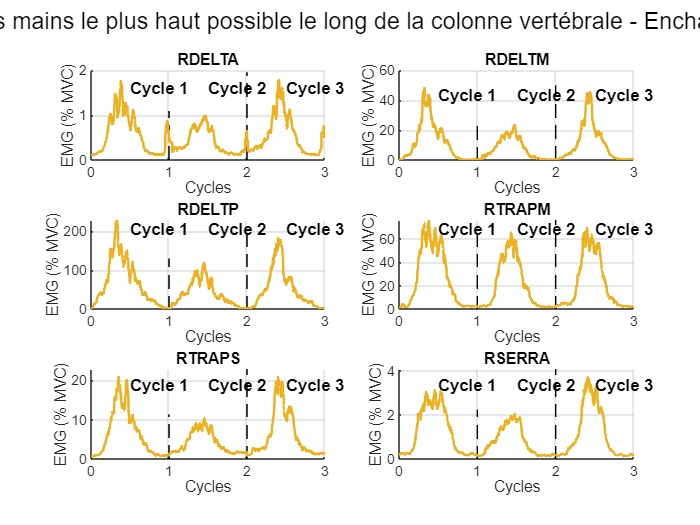


% Afficher l'enchaînement des cycles au lieu de la moyenne
% Récupération des données pour tous les cycles
subject_idx = 1;
functional_idx = selected_functional;

% Créer une figure pour l'enchaînement des cycles pour tous les muscles
figure;
sgtitle(sprintf('Sujet %s - %s - Enchaînement des %d cycles', subjects{1}, functional_labels{selected_functional}, num_available_cycles));

for m = 1:nb_muscles
    subplot(ceil(nb_muscles/2), 2, m);
    hold on;
    
    % Concaténer les données des cycles valides
    all_cycles_data = [];
    
    for cycle = 1:num_cycles
        cycle_data = all_functional_data{subject_idx, functional_idx, m, cycle};
        if ~isempty(cycle_data)
            % Ajouter une ligne verticale pour séparer les cycles (sauf avant le premier)
            if ~isempty(all_cycles_data)
                % Ajouter une ligne verticale à la fin du dernier cycle
                line([length(all_cycles_data)/num_points length(all_cycles_data)/num_points], [0 max(cycle_data)*1.1], 'Color', 'k', 'LineStyle', '--');
            end
            
            % Concaténer les données
            all_cycles_data = [all_cycles_data, cycle_data];
        end
    end
    
    % Créer un vecteur de temps pour l'enchaînement des cycles
    time_concatenated = linspace(0, length(all_cycles_data)/num_points, length(all_cycles_data));
    
    % Tracer l'enchaînement des cycles
    plot(time_concatenated, all_cycles_data, 'LineWidth', 1.5);
    
    % Ajouter des annotations pour les cycles
    for cycle = 1:num_available_cycles
        cycle_start = (cycle-1);
        text(cycle_start + 0.5, max(all_cycles_data)*0.9, sprintf('Cycle %d', cycle), 'FontWeight', 'bold');
    end
    
    title(muscles{m});
    ylabel('EMG (% MVC)');
    xlabel('Cycles');
    grid on;
end



% Création d'une grande matrice pour sauvegarder les données
% Format: 6 muscles (lignes) x temps concaténé pour les 3 cycles (colonnes)
all_data_matrix = zeros(nb_muscles, num_points * num_available_cycles);

% Remplissage de la matrice
for m = 1:nb_muscles
    col_start = 1;
    
    for cycle = 1:num_available_cycles
        cycle_data = all_functional_data{subject_idx, functional_idx, m, cycle};
        
        if ~isempty(cycle_data)
            % Calculer l'indice de fin pour ce cycle
            col_end = col_start + length(cycle_data) - 1;
            
            % S'assurer que nous ne dépassons pas les limites de la matrice
            if col_end <= size(all_data_matrix, 2)
                all_data_matrix(m, col_start:col_end) = cycle_data;
            else
                % Ajuster la taille si nécessaire
                all_data_matrix(m, col_start:size(all_data_matrix, 2)) = cycle_data(1:(size(all_data_matrix, 2)-col_start+1));
            end
            
            % Mettre à jour l'indice de début pour le prochain cycle
            col_start = col_end + 1;
        end
    end
end

% Affichage de la taille de la matrice pour vérification
fprintf('Matrice de données créée avec %d muscles et %d points temporels\n', ...
    size(all_data_matrix, 1), size(all_data_matrix, 2));

Matrice de données créée avec 6 muscles et 3000 points temporels



% % Sauvegarde de la matrice dans un fichier .mat
% save_filename = sprintf('%s_functional%d_data.mat', subjects{1}, functional_idx);
% save(save_filename, 'all_data_matrix', 'muscles', 'functional_labels', 'selected_functional', 'subjects');
% 
% fprintf('Données sauvegardées dans le fichier: %s\n', save_filename);

Données sauvegardées dans le fichier: YL03_functional4_data.mat


% 
% % Optionnel: Création d'une table pour une meilleure visualisation des données
% muscle_names = cell(nb_muscles, 1);
% for m = 1:nb_muscles
%     muscle_names{m} = muscles{m};
% end
% 
% all_data_table = array2table(all_data_matrix, 'RowNames', muscle_names);